clear


a0 = 2;
b0 = 1;

n = 10;

u = randn(1, n);

sigma = 1;

X = 1:n;
Y = a0*X + b0 + sigma*u;


X2 = X;
Y2 = Y;
for i = 1:length(X2)
    X2(i) = X2(i) * X(i);
    Y2(i) = Y2(i) * X(i);
end


A = [sum(X2), sum(X);
     sum(X) , n     ];
B = [sum(Y2);
     sum(Y) ];

coeffs = linsolve(A, B);
a = coeffs(1);
b = coeffs(2);


podgonka = a*X + b

podgonka =     3.1247    5.1389    7.1531    9.1673   11.1814   13.1956   15.2098   17.2240   19.2382   21.2524


nevyazka = Y - podgonka

nevyazka =    -1.0472    2.1755    0.4349   -0.4770   -1.2144    0.9077    0.1323   -2.4880   -1.1415    2.7177



skal = dot(podgonka, nevyazka);


sn = sqrt(sum(nevyazka.^2)/(n))

sn = 1.5311

% gamma = 0.95;
% tg = 1.96;
gamma = 0.90;
tg = 1.645;

ppp = (tg*sn/sqrt(n))*sqrt(1 + (X-sum(X)/n).^2/(sum((X-sum(X)/n).^2)/(n-1)));

f_plus = podgonka + ppp;
f_minus = podgonka - ppp;


a0

a0 = 2

b0

b0 = 1

a

a = 2.0142

b

b = 1.1105


skal

skal = -1.6342e-13

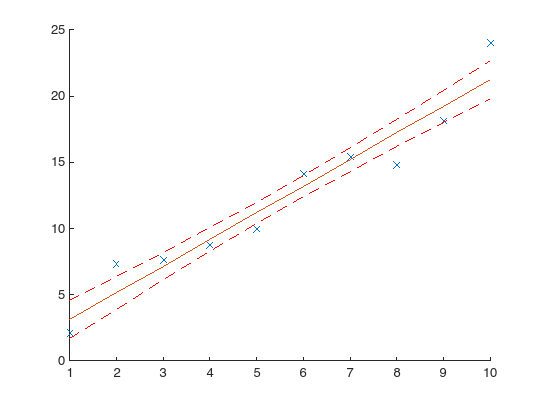


hold on
plot(X, Y, "x")
plot(X, podgonka)
plot(X, f_plus, "--r")
plot(X, f_minus, "--r")